# Metabotools tutorial I

In this tutorial we generate contextualized models of two lymphoblastic leukemia cell lines, CCRF-CEM and Molt- 4 cells, will be generated by integrating semi-quantitative metabolomic data, transcriptomic data, and growth rates. We will afterwards analyze the solution space of these models by sampling analysis.

Before running a section in the tutorial, read the corresponding sections in the MetaboTools protocol and supplemental tutorial (Data sheet 2, [http://journal.frontiersin.org/article/10.3389/fphys.2016.00327/full](http://journal.frontiersin.org/article/10.3389/fphys.2016.00327/full)). 

Clear workspace and initialize the COBRA Toolbox

clear
initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

## Step **0** Alter to define our own output location and LP solver!!

Define variables 

global CBTDIR % set path to cobratoolbox (pathToCOBRA)
% ouputPath = 'ADD YOUR PATH TO YOUR OUTPUT FOLDER'; %
% solver = 'ADD YOUR SOLVER'; %, e.g., 'cplex_direct' for ILOG

outputPath = pwd;
solver = 'glpk';

set and check solver

solverOK = changeCobraSolver(solver, 'LP');

if solverOK == 1
    fprintf('Solver %s is set.\n', solver);
else
    error('Solver %s could not be used. Check if %s is in the matlab path (set path) or check for typos', solver, solver);
end

Solver glpk is set.


load and check input is loaded correctly

tutorialPath = [CBTDIR filesep 'tutorials' filesep 'metabotools' filesep 'tutorial_I'];
if isequal(exist([tutorialPath filesep 'starting_model.mat'], 'file'), 2)  % 2 means it's a file.
    load([tutorialPath filesep 'starting_model.mat']);
    fprintf('The model is loaded.\n');
else
    error('The model ''starting_model'' could not be loaded.');
end

The model is loaded.


Check output path and writing permission

if ~exist(outputPath, 'dir') == 7
    error('Output directory in ''outputPath'' does not exist. Verify that you type it correctly or create the directory.');
end

% make and save dummy file to test writing to output directory
A = rand(1);
try
    save([outputPath filesep 'A']);
catch ME
    error('Files cannot be saved to the provided location: %s\nObtain rights to write into %s directory or set ''outputPath'' to a different directory.', outputPath, outputPath);
end

## Step 1: Shaping the model's environment using setMediumConstraints

RPMI medium composition.

medium_composition = {'EX_ala_L(e)'
                      'EX_arg_L(e)'
                      'EX_asn_L(e)'
                      'EX_asp_L(e)'
                      'EX_cys_L(e)'
                      'EX_gln_L(e)'
                      'EX_glu_L(e)'
                      'EX_gly(e)'
                      'EX_his_L(e)'
                      'EX_ile_L(e)'
                      'EX_leu_L(e)'
                      'EX_lys_L(e)'
                      'EX_met_L(e)'
                      'EX_phe_L(e)'
                      'EX_4HPRO(e)'
                      'EX_pro_L(e)'
                      'EX_ser_L(e)'
                      'EX_thr_L(e)'
                      'EX_trp_L(e)'
                      'EX_tyr_L(e)'
                      'EX_val_L(e)'
                      'EX_ascb_L(e)'
                      'EX_btn(e)'
                      'EX_chol(e)'
                      'EX_pnto_R(e)'
                      'EX_fol(e)'
                      'EX_ncam(e)'
                      'EX_pydxn(e)'
                      'EX_ribflv(e)'
                      'EX_thm(e)'
                      'EX_inost(e)'
                      'EX_ca2(e)'
                      'EX_fe3(e)'
                      'EX_k(e)'
                      'EX_hco3(e)'
                      'EX_na1(e)'
                      'EX_pi(e)'
                      'EX_glc(e)'
                      'EX_hxan(e)'
                      'EX_lnlc(e)'
                      'EX_lipoate(e)'
                      'EX_pyr(e)'
                      'EX_thymd(e)'
                      'EX_gthrd(e)'
                      'EX_anth(e)'
                      };

% Medium concentrations
met_Conc_mM = [0.1
               1.15
               0.15
               0.379
               0.208
               2
               0.136
               0.133
               0.0968
               0.382
               0.382
               0.274
               0.101
               0.0909
               0.153
               0.174
               0.286
               0.168
               0.0245
               0.129
               0.171
               0.00863
               0.00082
               0.0214
               0.000524
               0.00227
               0.082
               0.00485
               0.000532
               0.00297
               0.194
               0.424
               0
               5.33
               23.81
               127.26
               5.63
               11.11
               0
               0
               0
               1
               0
               0.00326
               0.0073
               ];

current_inf = 1000;
set_inf = 500;

cellConc = 2.17 * 1e6;
t = 48;
cellWeight = 3.645e-12;

Definition of basic medium (defines uptake from the medium, not captured by the medium composition, all with same constraints)

mediumCompounds = {'EX_co2(e)'; 'EX_h(e)'; 'EX_h2o(e)'; 'EX_hco3(e)'; 'EX_nh4(e)'; 'EX_o2(e)'; 'EX_pi(e)'; 'EX_so4(e)'};

mediumCompounds_lb = -100;

Additional constraints to limit the model behaviour, e.g., secretion of oxygen, essAA that need to be taken up (and that have not been measured).

customizedConstraints = {'EX_o2(e)'; 'EX_strch1(e)'; 'EX_acetone(e)'; 'EX_glc(e)'; 'EX_his_L(e)'; 'EX_val_L(e)'; 'EX_met_L(e)'};

customizedConstraints_lb = [-2.3460
                            0
                            0
                            -500
                            -100
                            -100
                            -100
                            ];

customizedConstraints_ub = [500
                            0
                            0
                            500
                            500
                            500
                            500
                            ];

[modelMedium, ~] = setMediumConstraints(starting_model, set_inf, current_inf, medium_composition, met_Conc_mM, cellConc, t, cellWeight, mediumCompounds, mediumCompounds_lb, customizedConstraints, customizedConstraints_ub, customizedConstraints_lb);

## Step **2** calculateLODs

ex_RXNS = {'EX_5mta(e)'
           'EX_uri(e)'
           'EX_chol(e)'
           'EX_ncam(e)'
           'EX_3mop(e)'
           'EX_succ(e)'
           'EX_pnto_R(e)'
           'EX_5oxpro(e)'
           'EX_thm(e)'
           'EX_anth(e)'
           'EX_4HPRO(e)'
           'EX_lac_L(e)'
           'EX_3mob(e)'
           'EX_his_L(e)'
           'EX_trp_L(e)'
           'EX_orn(e)'
           'EX_arg_L(e)'
           'EX_thr_L(e)'
           'EX_fol(e)'
           'EX_gln_L(e)'
           'EX_4pyrdx(e)'
           'EX_ser_L(e)'
           'EX_glc(e)'
           'EX_ribflv(e)'
           'EX_glu_L(e)'
           'EX_tyr_L(e)'
           'EX_phe_L(e)'
           'EX_inost(e)'
           'EX_Lcystin(e)'
           'EX_leu_L(e)'
           'EX_met_L(e)'
           'EX_cys_L(e)'
           'EX_asn_L(e)'
           'EX_mal_L(e)'
           'EX_ile_L(e)'
           'EX_pyr(e)'
           'EX_lys_L(e)'
           'EX_ala_L(e)'
           'EX_cit(e)'
           'EX_pro_L(e)'
           'EX_gly(e)'
           'EX_asp_L(e)'
           'EX_34hpp'
           'EX_octa(e)'
           'EX_4mop(e)'
           'EX_glyb(e)'
           'EX_val_L(e)'
           'EX_ade(e)'
           'EX_hxan(e)'
           'EX_gua(e)'
           'EX_ins(e)'
           'EX_orot(e)'
           'EX_ura(e)'
           'EX_ahcys(e)'
           'EX_cbasp(e)'
           'EX_Lcystin(e)'
           'EX_ser_L(e)'
           'EX_cys_L(e)'
           'EX_thm(e)'
           'EX_arg_L(e)'
           'EX_ncam(e)'
           };

theo_mass = [298.0974
             243.0617
             104.1075
             123.0558
             129.0552
             117.0188
             220.1185
             128.0348
             265.1123
             138.0555
             132.0661
             89.0239
             115.0395
             156.0773
             205.0977
             133.0977
             175.1195
             120.0661
             440.1319
             147.077
             182.0453
             106.0504
             179.0556
             377.1461
             148.061
             182.0817
             166.0868
             179.0556
             241.0317
             132.1025
             150.0589
             122.0276
             133.0613
             133.0137
             132.1025
             87.0082
             147.1134
             90.0555
             191.0192
             116.0712
             74.0242
             134.0453
             180.157
             172.265
             130.142
             118.0868
             118.0868
             136.0623
             137.0463
             152.0572
             267.0729
             155.0093
             111.0195
             385.1294
             175.0355
             241.0317
             106.0504
             122.0276
             265.1123
             175.1195
             123.0558
             ];

lod_ngmL = [0.3
            1.7
            2.8
            3
            3.5
            3.9
            4
            4.8
            6.1
            7.7
            8.1
            10.9
            11.2
            13.6
            15.7
            16.9
            24.8
            25.6
            25.7
            28.4
            32.7
            37.5
            44
            45
            45
            47.4
            48.4
            59
            59.7
            68.9
            74.1
            77
            82.1
            99.2
            112.9
            121.3
            131.7
            133.5
            150.8
            169.2
            214.3
            229.5
            537.3
            10.9
            3.5
            2.8
            28.2
            1.6
            0.8
            48.9
            8.8
            37.1
            52.4
            50
            229.5
            59.7
            37.5
            77
            6.1
            24.8
            3
            ];

[lod_mM] = calculateLODs(theo_mass, lod_ngmL);

## Step **3** define Uptake and Secretion Profiles

exclude_upt = {'EX_gln_L(e)'; 'EX_cys_L(e)'; 'EX_ala_L(e)'; 'EX_mal_L(e)'; 'EX_fol(e)'};
exclude_secr = {'EX_gln_L(e)'; 'EX_cys_L(e)'; 'EX_ala_L(e)'};

add_secr = {'EX_mal_L(e)'};
add_upt = {};
essAA_excl = {'EX_his_L(e)'; 'EX_ile_L(e)'; 'EX_leu_L(e)'; 'EX_lys_L(e)'; 'EX_met_L(e)'; 'EX_phe_L(e)'; 'EX_thr_L(e)'; 'EX_trp_L(e)'; 'EX_val_L(e)'};

tol = 0.05;

data_RXNS = {'EX_orn(e)'
             'EX_mal_L(e)'
             'EX_lac_L(e)'
             'EX_gly(e)'
             'EX_glu_L(e)'
             'EX_cit(e)'
             'EX_5oxpro(e)'
             'EX_4mop(e)'
             'EX_3mop(e)'
             'EX_3mob(e)'
             'EX_tyr_L(e)'
             'EX_trp_L(e)'
             'EX_thr_L(e)'
             'EX_pyr(e)'
             'EX_phe_L(e)'
             'EX_lys_L(e)'
             'EX_leu_L(e)'
             'EX_ile_L(e)'
             'EX_glc(e)'
             'EX_chol(e)'
             'EX_anth(e)'
             'EX_val_L(e)'
             'EX_met_L(e)'
             'EX_his_L(e)'
             'EX_gln_L(e)'
             'EX_cys_L(e)'
             'EX_ala_L(e)'
             'EX_pi(e)'
             'EX_asp_L(e)'
             'EX_4HPRO(e)'
             'EX_pnto_R(e)'
             'EX_pro_L(e)'
             'EX_fol(e)'
             };

Molt-4

input_A = [
    % control TP 1	control TP 2	Cond TP 1	Cond TP 2
    65245.09667	68680.93	54272.41667	65159.50333
    3000	30970.784	20292.406	27226.6555
    2038946.433	1917042.967	5654513.467	101768253
    163882.9467	186682.92	121762.3567	310547.7
    473539.8667	455197.4667	462903.8333	1024508.5
    8681.527333	8704.7345	9459.837	34177.945
    29168.15	21808.73	120655.9867	2060525.467
    3000	3000	34436.50433	113668.5123
    3000	3000	25108.829	121927.3673
    3000	3000	3000	14717.55667
    4142302	4063607.667	3934639.333	3075783.333
    2153692	2132723.667	2037735.333	1387754.333
    406102.2667	417512.6333	381085.2333	259555.2667
    465074.6	387569.1333	439148.0667	210407.8333
    8087955	8345511.333	8215168.333	5360276
    198435.8	195675.8	188473.1	112386.1667
    20823770.33	20801258.67	19725086.67	15148808
    21229254.67	21225778.33	20799761	17160163
    76555640.67	71459886.33	61697085.33	34981419.33
    876300.4333	905132.5	892182.2	541860.4667
    159124.46	178538.2167	162567.13	3000
    2857012.667	2900419.667	2853523.667	1793173.667
    2995910.333	3018536.333	3024630.333	2266832.333
    69077.16333	67843.12	69406.69	95624.28
    3000	3000	824549.3667	2283200.867
    45304.84667	52977.77333	56566.27667	60759.23
    1613345.1	1258710.1	3430342.067	25970024.1
    216828142.3	221118425	223518663	216863897.3
    632160.0333	612562.3	590881.7333	940705.6
    814465.8333	786011.5667	630513.4	622493.9
    84638.70667	86751.96	89717.10667	68882.68333
    5107317.333	5168599.333	5163708.333	5263614.333
    95419.73667	105904.7067	97550.78667	102678.49
];

CCRF-CEM

input_B = [
    % control 2 TP 1	control 2 TP 2	Cond 2 TP 1	Cond 2 TP 2
    65245.09667	68680.93	73850.77	98489.89
    3000	30970.784	3000	94181.77233
    2038946.433	1917042.967	5222377.933	134980059.9
    163882.9467	186682.92	219683.7	460476.5267
    473539.8667	455197.4667	437398.3667	630407.2667
    8681.527333	8704.7345	8317.144	86546.77933
    29168.15	21808.73	62146.47333	1012932.38
    3000	3000	9918.992	129433.4973
    3000	3000	7222.259333	145547.7347
    3000	3000	3000	17641.55667
    4142302	4063607.667	4023284.333	3489981.333
    2153692	2132723.667	2068977	1570648
    406102.2667	417512.6333	386495.2	303808.2
    465074.6	387569.1333	376779.1	249036.3333
    8087955	8345511.333	8237784.667	6540301.667
    198435.8	195675.8	196447.1	149861.6667
    20823770.33	20801258.67	21119935.67	16346765.67
    21229254.67	21225778.33	20790535.33	17219085
    76555640.67	71459886.33	65009057.67	24330565.33
    876300.4333	905132.5	884112.5667	259273.9333
    159124.46	178538.2167	158271.14	60631.19333
    2857012.667	2900419.667	2668140	2790196.333
    2995910.333	3018536.333	2890029.333	2538211
    69077.16333	67843.12	74035.24	86165.55
    3000	3000	323185.6667	2063962.067
    45304.84667	52977.77333	62076.23333	64524.22333
    1613345.1	1258710.1	2788313.567	30868376.53
    216828142.3	221118425	212276379	208623151.3
    632160.0333	612562.3	680373.4333	770903.9333
    814465.8333	786011.5667	679862.7	582257.4667
    84638.70667	86751.96	88002.12	99449.36667
    5107317.333	5168599.333	5134219	4445918.333
    95419.73667	105904.7067	100629.24	84807.62333
];

[cond1_uptake, cond2_uptake, cond1_secretion, cond2_secretion, slope_Ratio] = defineUptakeSecretionProfiles(input_A, input_B, data_RXNS, tol, essAA_excl, exclude_upt, exclude_secr, add_secr, add_upt);

MANIPULATE OUTPUT: Add secretion without data points to secretion condition 2.

add_secretion = {'EX_4pyrdx(e)'
                 'EX_34hpp'
                 'EX_uri(e)'
                 'EX_succ(e)'
                 'EX_glyb(e)'
                 'EX_5mta(e)'
                 'EX_asn_L(e)'};

remove_secretion = {'EX_asp_L(e)'; 'EX_pnto_R(e)'};
remove_uptake = {'EX_met_L(e)'};
add_uptake = {'EX_fol(e)'};  % folate uptake in CEM

cond2_secretion = [cond2_secretion; add_secretion];
cond2_secretion(find(ismember(cond2_secretion, remove_secretion))) = [];
cond2_uptake = [cond2_uptake; add_uptake];
cond2_uptake(find(ismember(cond2_uptake, remove_uptake))) = [];

## Step **4** Calculate Quantitative Diffs

[cond1_upt_higher, cond2_upt_higher, cond2_secr_higher, cond1_secr_higher, cond1_uptake_LODs, cond2_uptake_LODs, cond1_secretion_LODs, cond2_secretion_LODs] = calculateQuantitativeDiffs(data_RXNS, slope_Ratio, ex_RXNS, lod_mM, cond1_uptake, cond2_uptake, cond1_secretion, cond2_secretion);

MANIPULATE OUTPUT: Remove the metabolites from the uptake and secretion profiles that you adjusted in the previous steps, e.g. those for which you assume a different directionality as in the data, for metabolites that have inconclusive data (e.g., in case of the anth the metabolite was not detected in the 48 hr samples. It coulod be assumed that all of it (down to the LOD) was consumed, however in the case of the two cell lines, the relative difference between the cell lines based on the slope ratio (of consumption) would have been 1975% higher in Molt-4 compared the CCRF-CEM cells. In order to prevent that this extreme point distorts the results, these metabolites need t be removed from the input for semi-quantitative adjustment unless such large differences are justified, and make biological sense).

remove = {'EX_anth(e)'; 'EX_ile_L(e)'};

A = [];
for i = 1:length(cond2_upt_higher)
    if find(ismember(remove, cond2_upt_higher{i, 1})) > 0
        A = [A; i];
    end
end
cond2_upt_higher(A, :) = [];

## Step **5** setQualitativeConstraints

cellConc = 2.17 * 1e6;
t = 48;
cellWeight = 3.645e-12;

Molt-4 model

ambiguous_metabolites = {'EX_ala_L(e)'; 'EX_gln_L(e)'; 'EX_cys_L(e)'};  % for ala and gln, we do not know if they are taken up or secreted. Small amounts of cysteine are required for proteins, therefore uptake of cys is likely to be small compared to other metabolites.

basisMedium = {'EX_o2(e)'; 'EX_strch1(e)'; 'EX_acetone(e)'; 'EX_glc(e)'; 'EX_his_L(e)'; 'EX_ca2(e)'; 'EX_cl(e)'; 'EX_co(e)'; 'EX_fe2(e)'; 'EX_fe3(e)'; 'EX_k(e)'; 'EX_na1(e)'; 'EX_i(e)'; 'EX_sel(e)'; 'EX_co2(e)'; 'EX_h(e)'; 'EX_h2o(e)'; 'EX_hco3(e)'; 'EX_nh4(e)'; 'EX_o2(e)'; 'EX_pi(e)'; 'EX_so4(e)'};

[model_A] = setQualitativeConstraints(modelMedium, cond1_uptake, cond1_uptake_LODs, cond1_secretion, cond1_secretion_LODs, cellConc, t, cellWeight, ambiguous_metabolites, basisMedium);

CCRF-CEM model ModelB

ambiguous_metabolites = {'EX_ala_L(e)'; 'EX_gln_L(e)'; 'EX_pydxn(e)'; 'EX_cys_L(e)'};

basisMedium = {'EX_ca2(e)'; 'EX_cl(e)'; 'EX_co(e)'; 'EX_fe2(e)'; 'EX_fe3(e)'; 'EX_k(e)'; 'EX_na1(e)'; 'EX_i(e)'; 'EX_sel(e)'; 'EX_co2(e)'; 'EX_h(e)'; 'EX_h2o(e)'; 'EX_hco3(e)'; 'EX_nh4(e)'; 'EX_o2(e)'; 'EX_pi(e)'; 'EX_so4(e)'; 'EX_his_L(e)'; 'EX_o2(e)'; 'EX_strch1(e)'; 'EX_acetone(e)'; 'EX_glc(e)'; 'EX_val_L(e)'; 'EX_met_L(e)'};

[model_B] = setQualitativeConstraints(modelMedium, cond2_uptake, cond2_uptake_LODs, cond2_secretion, cond2_secretion_LODs, cellConc, t, cellWeight, ambiguous_metabolites, basisMedium);

## Step **5** setSemiQuantConstraints

This function applies the constraints to the models. It takes two condition specific models into consideration.

[modelA_QUANT, modelB_QUANT] = setSemiQuantConstraints(model_A, model_B, cond1_upt_higher, cond2_upt_higher, cond2_secr_higher, cond1_secr_higher);

## Step **6** Apply growth constraints

of = 'biomass_reaction2';
tolerance = 20;

set constraints on MOLT4 model

fprintf('Set contraints on MOLT4 model\n');

Set contraints on MOLT4 model



dT = 19.6;

[model_A_BM] = setConstraintsOnBiomassReaction(modelA_QUANT, of, dT, tolerance);

set constraints on CCRF-CEM model

dT = 22;

[model_B_BM] = setConstraintsOnBiomassReaction(modelB_QUANT, of, dT, tolerance);

## Step **7** integrateGeneExpressionData

dataGenes = [535
             1548
             2591
             3037
             4248
             4709
             6522
             7167
             7367
             8399
             23545
             129807
             221823
             ];

[model_A_GE] = integrateGeneExpressionData(model_A_BM, dataGenes);

dataGenes = [239
             443
             535
             1548
             2683
             3037
             4248
             4709
             5232
             6522
             7364
             7367
             8399
             23545
             54363
             66002
             129807
             221823
             ];

[model_B_GE] = integrateGeneExpressionData(model_B_BM, dataGenes);

## Step **8** extractConditionSpecificModel

theshold = 1e-6;
model = model_A_GE;
[model_Molt] = extractConditionSpecificModel(model, theshold);

Starting parallel pool (parpool) using the 'local' profile ... 

connected to 12 workers.


[model_CEM] = extractConditionSpecificModel(model_B_GE, theshold);

[MetConn, RxnLength] = networkTopology(modelMedium);
[MetConnA, RxnLengthA] = networkTopology(model_Molt);
[MetConnB, RxnLengthB] = networkTopology(model_CEM);
MetConnCompare = sort(MetConn, 'descend');
MetConnCompareA = sort(MetConnA, 'descend');
MetConnCompareB = sort(MetConnB, 'descend');

Plot metabolite connectivity

figure
semilogy(sort(MetConnCompare, 'descend'), 'ro')
hold

Current plot held


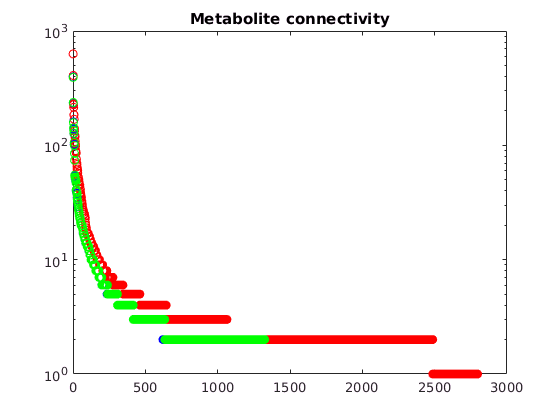

semilogy(sort(MetConnCompareA, 'descend'), 'bo')
semilogy(sort(MetConnCompareB, 'descend'), 'go')
title('Metabolite connectivity')

## Step **9** perform sampling analysis

fprintf('Perform sampling analysis\n');

Perform sampling analysis



warmupn = 2000;
nFiles = 10;
pointsPerFile = 1000;
stepsPerPoint = 500;
fileBaseNo = 0;
maxTime = 3600000;

fileName = 'modelA';
performSampling(model_Molt, warmupn, fileName, nFiles, pointsPerFile, stepsPerPoint, fileBaseNo, maxTime, outputPath);

Creating warmup points ...



fileName = 'modelB';
performSampling(model_CEM, warmupn, fileName, nFiles, pointsPerFile, stepsPerPoint, fileBaseNo, maxTime, outputPath);

Creating warmup points ...

summarize sampling results

fonts = 8;
nFiles = 10;
pointsPerFile = 1000;
starting_Model = modelMedium;
hist_per_page = 4;
bin = 30;
modelA = model_Molt;

modelB = model_CEM;

dataGenes = [32
             205
             411
             412
             1537
             1608
             1632
             1645
             1737
             1757
             2108
             2184
             2224
             2539
             ];

show_rxns = {'PYK'
             'SUCD1m'
             'ATPS4m'
             'ETF'
             };

[stats, statsR] = summarizeSamplingResults(modelA, modelB, outputPath, nFiles, pointsPerFile, starting_Model, dataGenes, show_rxns, fonts, hist_per_page, bin, 'modelA', 'modelB');

Loading samples ...
10%     [....                                    ]��������������������������������������������������20%     [........                                ]��������������������������������������������������30%     [............                            ]��������������������������������������������������40%     [................                        ]��������������������������������������������������50%     [....................                    ]��������������������������������������������������60%     [........................                ]��������������������������������������������������70%     [............................            ]��������������������������������������������������80%     [................................        ]��������������������������������������������������90%     [....................................    ]��������������������������������������������������100%    [........................................]
Loading samples ...
10%     [

Starting parallel pool (parpool) using the 'local' profile ... connected to 12 workers.
Saving results to /home/syarra/Dropbox/uni.lu/github/opencobra/cobratoolbox/tutorials/metabotools/tutorial_I/sampling_page1.png.



clearvars -EXCEPT model_Molt model_CEM modelMedium stats statsR